# **Escuela Politécnica Nacional**

# **Redes Neuronales**

# **Tarea 6: Dataset Wifi Localization**

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-15

En este apartado analizaremos mediante diferentes algoritmos el Dataset Wifi Localization, el cual comprende un problema de clasiicación multiclase.

**DT = **Decision Tree

**RF = **Random Forest

**DNN**= Deep Neuronal Network

**LDA = **Linear Discriminant Analysis

**ANFIS =  **Adaptive Neuro Fuzzy Inference System

**t-SNE =**  t-Distributed Stochastic Neighbor Embedding (t-SNE) 

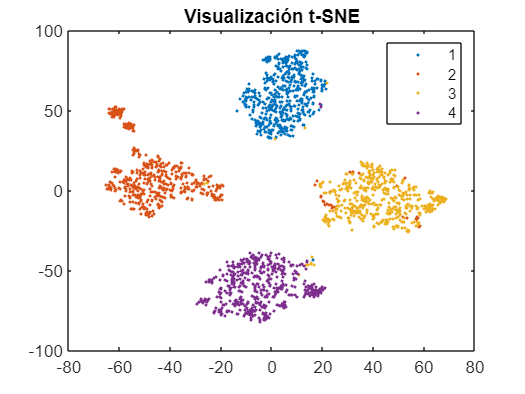

% Dataset Wifi Localization
tic
clc;
clear;
rng(0);
warning("off","all");

% Carga y limpieza de datos
T = readtable("wifi_localization.txt","ReadVariableNames",false);
T = rmmissing(T);

X = table2array(T(:,1:7));
Y = table2array(T(:,8));

% Visualización t-SNE (2 dimensiones)
Y_tsne = tsne(X, "Algorithm", "exact");

figure;
gscatter(Y_tsne(:,1), Y_tsne(:,2), Y);
title("Visualización t-SNE");

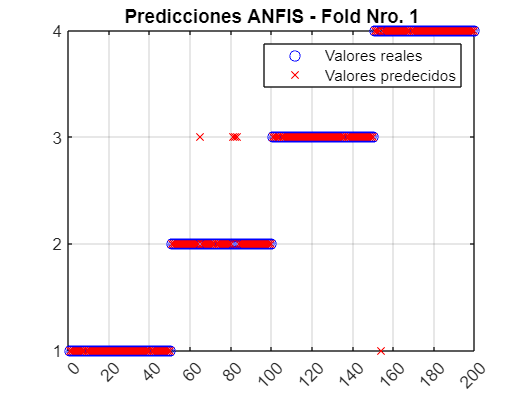

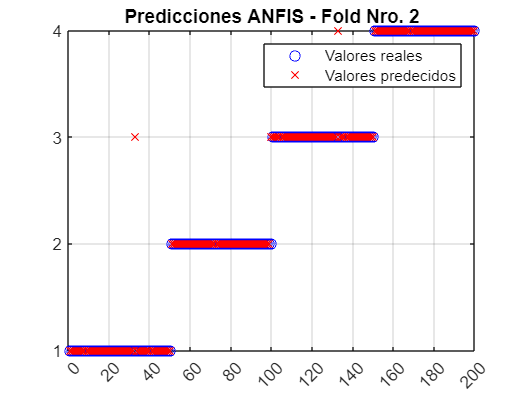

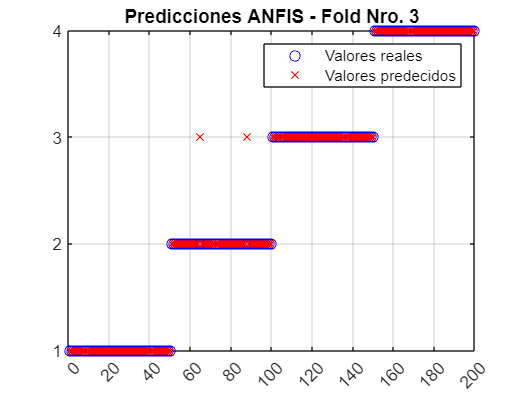

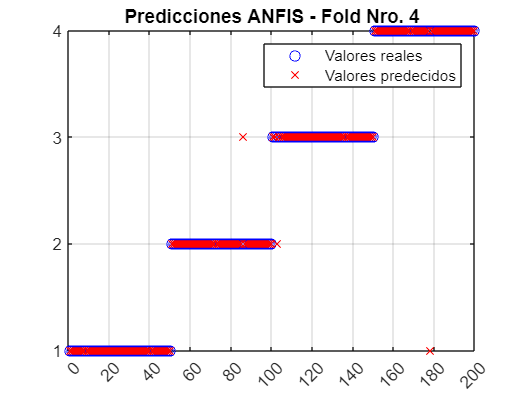

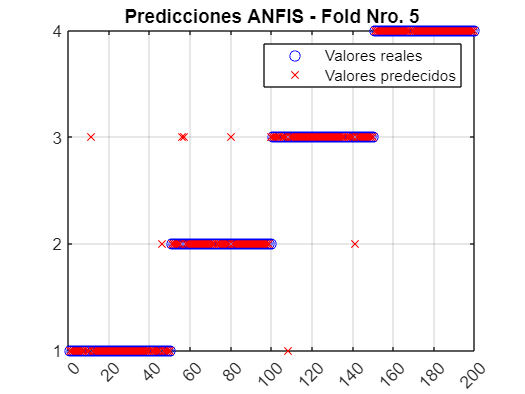

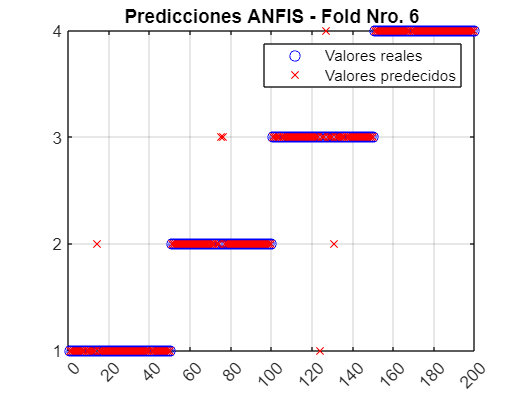

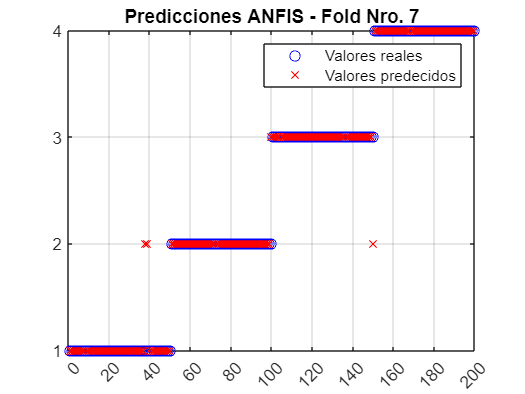

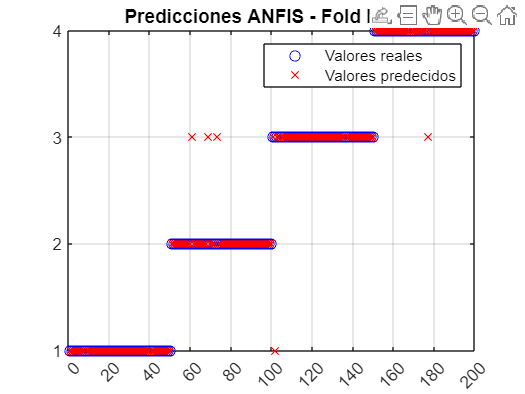


rng(0);

% Reducción de dimensionalidad
Xred = [Y_tsne(:,1), Y_tsne(:,2)];

% Método 10-folding
CVO = cvpartition(Y,"k",10);
num_pruebas = CVO.NumTestSets;

for i = 1:num_pruebas
    trIdx = CVO.training(i);
    teIdx = CVO.test(i);
    
    % Decision Tree
    ctree = fitctree(X(trIdx,:),Y(trIdx,:), "MinLeafSize", 25);
    Ypred_dt = predict(ctree, X(teIdx,:));
    Met_dt(:,i)=Metricas(Y(teIdx,:), Ypred_dt);
    
    % Random Forest
    rf = TreeBagger(200, X(trIdx,:), Y(trIdx,:), "Method", "classification", "OOBPrediction", "On", "MinLeafSize", 25);
    Ypred_rf = str2double(predict(rf, X(teIdx,:)));
    Met_rf(:,i)=Metricas(Y(teIdx,:), Ypred_rf);

    % Deep Neuronal Network
    dnn = fitcnet(X(trIdx,:), Y(trIdx,:), ...
         "LayerSizes", [32 10], ...
         "Activations", "sigmoid", ...
         "Lambda", 1e-6, ...
         "IterationLimit", 5000, ...
         "Standardize", true);
    Ypred_dnn = predict(dnn, X(teIdx,:));
    Met_dnn(:,i) = Metricas(Y(teIdx,:), Ypred_dnn);

    % LDA
    lda = fitcdiscr(X(trIdx,:), Y(trIdx,:));
    Ypred_lda = predict(lda, X(teIdx,:));
    Met_lda(:,i) = Metricas(Y(teIdx,:), Ypred_lda);

    % ANFIS
    opt = anfisOptions;
    opt.InitialFIS = 5;
    opt.EpochNumber = 150;
    opt.OptimizationMethod = 1;
    opt.DisplayANFISInformation = 0;
    opt.DisplayErrorValues = 0;
    opt.DisplayStepSize = 0;
    opt.DisplayFinalResults = 0;

    anfis_model = anfis([Xred(trIdx,:) Y(trIdx,:)], opt);
    Ypred_anfis = round(evalfis(anfis_model, Xred(teIdx,:)));
    Met_anfis(:,i) = Metricas(Y(teIdx,:), Ypred_anfis);

    % Gráfica de predicciones ANFIS
    figure;
    plot(Y(teIdx,:),"ob");
    hold on
    plot(Ypred_anfis,"xr")
    grid on;
    title(strcat("Predicciones ANFIS - Fold Nro. ", string(i)));
    legend("Valores reales","Valores predecidos");
    ax = gca;
    ax.XTick = unique(round(ax.XTick));
    ax.YTick = unique(round(ax.YTick));
    hold off;
end


Metricas_dt = mean(Met_dt,2)

Metricas_dt =     0.9648
    0.9645
    0.9644
    0.9645
    0.0355


Metricas_rf = mean(Met_rf,2)

Metricas_rf =     0.9781
    0.9775
    0.9775
    0.9775
    0.0225


Metricas_dnn = mean(Met_dnn,2)

Metricas_dnn =     0.9801
    0.9795
    0.9795
    0.9795
    0.0205


Metricas_lda = mean(Met_lda,2)

Metricas_lda =     0.9738
    0.9710
    0.9713
    0.9710
    0.0290


Metricas_anfis = mean(Met_anfis,2)

Metricas_anfis =     0.9786
    0.9780
    0.9780
    0.9780
    0.0220


toc

Elapsed time is 140.279049 seconds.


**Conclusión**

Se puede concluir, de manera general, que para todos los casos las métricas de menor valor corresponden a las obtenidas a través del árbol de decisión individual (DT).

Para el problema de clasificación, las mejores métricas fueron obtenidas con la red neuronal profunda (DNN), seguido de la red ANFIS y de Random Forest (RF). Los valores de métricas más bajos fueron obtenidos por LDA y el árbol de decisión individual, siendo superiores los valores obtenidos con LDA.

Además, se puede concluir que una técnica de reducción de la dimensionalidad como t-Distributed Stochastic Neighbor Embedding (t-SNE) como paso previo puede ser de utilidad para alimentar de información a ANFIS y así reducir los tiempos de procesamiento y obtener mejores resultados.